clear all;
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

s1=-0.9;s2=sqrt(1-s1^2);s3=0;
theta=acos(s1)/2;
delta=acos(s2/sin(2*theta));

% phi=0;psi=pi/2;theta=pi/4;
% delta=phi-psi;

alpha_v=5;alpha_T=20/3;
F=5/2;
sigmay^2

ans =     1.2500         0   -1.5811         0         0         0
         0    3.2500         0   -2.1213         0         0
   -1.5811         0    4.2500         0   -2.1213         0
         0   -2.1213         0    4.2500         0   -1.5811
         0         0   -2.1213         0    3.2500         0
         0         0         0   -1.5811         0    1.2500


sigmax^2

ans =     1.2500         0    1.5811         0         0         0
         0    3.2500         0    2.1213         0         0
    1.5811         0    4.2500         0    2.1213         0
         0    2.1213         0    4.2500         0    1.5811
         0         0    2.1213         0    3.2500         0
         0         0         0    1.5811         0    1.2500


vector=alpha_v*sin(2*theta)*sin(-delta)*sigmax/F/2;
tensor=alpha_T/(2*F*(2*F-1))*(6*(cos(theta))^2*sigmay^2+ ...
    6*(sin(theta))^2*sigmaz^2+ ...
    3*sin(2*theta)*cos(delta)*(1i*sigmax+2*sigmaz*sigmay));

ham=vector+tensor;


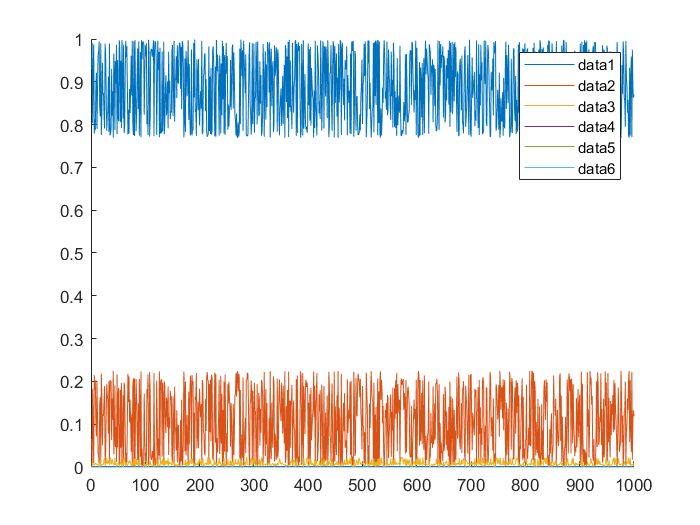

scatter_number=100-1;
theta=[0:pi/scatter_number:pi];
phi=[0:2*pi/scatter_number:pi*2];
inital_state=[1 0 0 0 0 0]';
sample_num=1000;center=100;sigma=1;
density_matrix=zeros(6,6);
for i=1:sample_num
    distribution=normrnd(center,sigma);
    ham_piover2=sigmay;
    ham_precession=1*sigmaz+1*distribution.*ham;
    transverse_polar=ham_evolve(ham_piover2,inital_state,0);
    precess_state=ham_evolve(ham_precession,transverse_polar,100000);
    final_state=ham_evolve(ham_piover2,precess_state,0);
    singlestate_population(:,i)=abs(final_state).^2;
    
end
sumup_population=mean(singlestate_population,2);
figure;hold on;
for i=1:6
    plot([1:sample_num],singlestate_population(i,:));
end
legend;

average_population=sum(singlestate_population,2)/sample_num;


figure;
matrixplot(abs(density_matrix),'DisplayOpt','On','ColorBar','On','Grid','Off', ...
    'XVarName',{'1' '2' '3' '4' '5' '6'}, 'YVarName',{'1' '2' '3' '4' '5' '6'});
colormap summer;
%set(gca,"Clim",[0 1]);
for i=1:length(theta)
    theta_in=theta(i);
    for j=1:length(phi)
        phi_in=phi(j);
        result(i,j)=spin_coherent(theta_in,phi_in)'*density_matrix*spin_coherent(theta_in,phi_in);
    end
end

function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
